% AAE 532 HW 10 Problem 3
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps10';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
mars = planet_consts.mars;  % structure of mars
earth = planet_consts.earth;  % structure of earth
sun = planet_consts.sun;  % structure of sun
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)
% Assumptions 
% ** TYPE-1 transfer
TrA = 120;  % transfer angle [deg]
TOF_days = 92;  % [days]
TOF = TOF_days * 60 * 60 * 24;  % TOF [s]

% Determine the TYPE of the transfer orbit
mu_sun = sun.gp  % gravitational parameter of sun

mu_sun = 1.3271e+11

mu_earth = earth.gp  % gravitational parameter of earth 

mu_earth = 3.9860e+05

mu_mars = mars.gp  % gravitational parameter of mars 

mu_mars = 4.2828e+04

R_mars = mars.mer  % radius of Mars

R_mars = 3397

R_earth = earth.mer  % radius of earth

R_earth = 6.3781e+03


r1 = earth.smao  % the first leg of the space triangle equal to the semi-major axis of earth

r1 = 149597898

r2 = mars.smao  % the second leg of the space triangle equal to the semi-major axis of mars

r2 = 227944135

v1 = sqrt(mu_sun / r1)  % initial velocity in the orbit of earth

v1 = 29.7847

v2 = sqrt(mu_sun / r2)  % final velocity in the orbit of mars

v2 = 24.1291


c = sqrt(r1^2 + r2^2 - 2*r1*r2*cosd(TrA))  % chord length of the space triangle

c = 3.2930e+08

s = (r1 + r2 + c) / 2  % semi-perimeter 

s = 3.5342e+08

% (b)
% The orbit is TYPE-1H
a_min = s/2  % the minimum possible semi-major axis of the transfer orbit

a_min = 1.7671e+08

[a, alpha, beta, fval] = find_lambertHyp_SMA(s, c, TOF, mu_sun, a_min, "1H")

Optimization terminated: mesh size less than options.MeshTolerance.


a = -8.2606e+08

alpha = 0.8949

beta = 0.2411

fval = 0.4842

rad2deg(alpha)

ans = 51.2724

rad2deg(beta)

ans = 13.8128

[p, p_db, e, TA_dep, TA_arr, TA_dep_db, TA_arr_db] = find_lambertX_hyp(a, alpha, beta, ...
    TrA, s, c, r1, r2)

p = 2.7962e+08

p_db = 	1.0e+08 *

    2.7962    0.8629


e = 1.1569

TA_dep = -41.3007

TA_arr = 78.6993

TA_dep_db =    41.3007  -41.3007  113.7475 -113.7475


TA_arr_db =    78.6993  -78.6993  126.2525 -126.2525


H1 = T2H_anomaly(e, TA_dep, "deg")

H1 = -11.6896

H2 = T2H_anomaly(e, TA_arr, "deg")

H2 = 25.7699

t1 = sqrt(abs(a)^3 / mu_sun) * (e * sinh(deg2rad(H1)) - deg2rad(H1))

t1 = -2.1936e+06

t2 = sqrt(abs(a)^3 / mu_sun) * (e * sinh(deg2rad(H2)) - deg2rad(H2))

t2 = 5.7552e+06

T = t2 - t1 

T = 7.9488e+06

if ~(round(T / 60 / 60 / 24) == (TOF / 60 / 60 / 24))
    error("TA is not the difference of true anomalies")
end
TA_dep 

TA_dep = -41.3007

TA_arr

TA_arr = 78.6993

% Calculate energy
En = -mu_sun / 2 / a

En = 80.3290

v_dep = vis_viva(r1, a, mu_sun)

v_dep = 43.9877

v_arr = vis_viva(r2, a, mu_sun)

v_arr = 36.4018

FPA_dep = acos_dbval(sqrt(mu_sun * p)/r1 / v_dep, "deg")

FPA_dep =    22.2211  -22.2211


FPA_arr = acos_dbval(sqrt(mu_sun * p)/r2 / v_arr, "deg")

FPA_arr =    42.7637  -42.7637


FPA_dep = FPA_dep(FPA_dep < 0)

FPA_dep = -22.2211

FPA_arr = FPA_arr(FPA_arr > 0)

FPA_arr = 42.7637

rp = a * (1 - e)

rp = 1.2964e+08

% (c)
% Departure 
Dv_dep = sqrt(v_dep^2 + v1^2 - 2 * v_dep * v1 * cosd(FPA_dep))

Dv_dep = 19.9081

beta1 = asin_dbval(v1 / Dv_dep * sind(FPA_dep), "deg")

beta1 =   -34.4580 -145.5420


beta2 = acos_dbval((Dv_dep^2 + v_dep^2 - v1^2)/2/v_dep/Dv_dep, "deg")

beta2 =    34.4580  -34.4580


beta = intersect(round(beta1,4), round(beta2,4))

beta = -34.4580

alpha_dep = beta + FPA_dep

alpha_dep = -56.6791

Dv_dep_vec.vnb = Dv_dep * [cosd(alpha_dep), sind(alpha_dep)]

Dv_dep_vec = struct with fields:
    vnb: [10.9361 -16.6353]


% Arrival 
Dv_arr = sqrt(v_arr^2 + v2^2 - 2 * v_arr * v2 * cosd(FPA_arr))

Dv_arr = 24.8519

beta1 = asin_dbval(v_arr / Dv_arr * sind(FPA_arr), "deg")

beta1 =    84.0050   95.9950


beta2 = acos_dbval((v2^2 + Dv_arr^2 - v_arr^2)/2/v2/Dv_arr, "deg")

beta2 =    95.9950  -95.9950


beta = intersect(round(beta1,4), round(beta2,4))

beta = 95.9950

alpha_arr =  beta + FPA_arr

alpha_arr = 138.7587

Dv_arr_vec.vnb = Dv_arr * [cosd(alpha_arr), -sind(alpha_arr)]

Dv_arr_vec = struct with fields:
    vnb: [-18.6871 -16.3831]


% Total
Dv_tot = Dv_dep + Dv_arr

Dv_tot = 44.7599

% (d)
% Plotting

% Earth Orbit
angles = 0:360;
X_earth = earth.smao * cosd(angles); Y_earth = earth.smao * sind(angles);

% Transfer Orbit
angles = TA_dep:0.0001:TA_arr

angles =   -41.3007  -41.3006  -41.3005  -41.3004  -41.3003  -41.3002  -41.3001  -41.3000  -41.2999  -41.2998  -41.2997  -41.2996  -41.2995  -41.2994  -41.2993  -41.2992  -41.2991  -41.2990  -41.2989  -41.2988  -41.2987  -41.2986  -41.2985  -41.2984  -41.2983  -41.2982  -41.2981  -41.2980  -41.2979  -41.2978  -41.2977  -41.2976  -41.2975  -41.2974  -41.2973  -41.2972  -41.2971  -41.2970  -41.2969  -41.2968  -41.2967  -41.2966  -41.2965  -41.2964  -41.2963  -41.2962  -41.2961  -41.2960  -41.2959  -41.2958


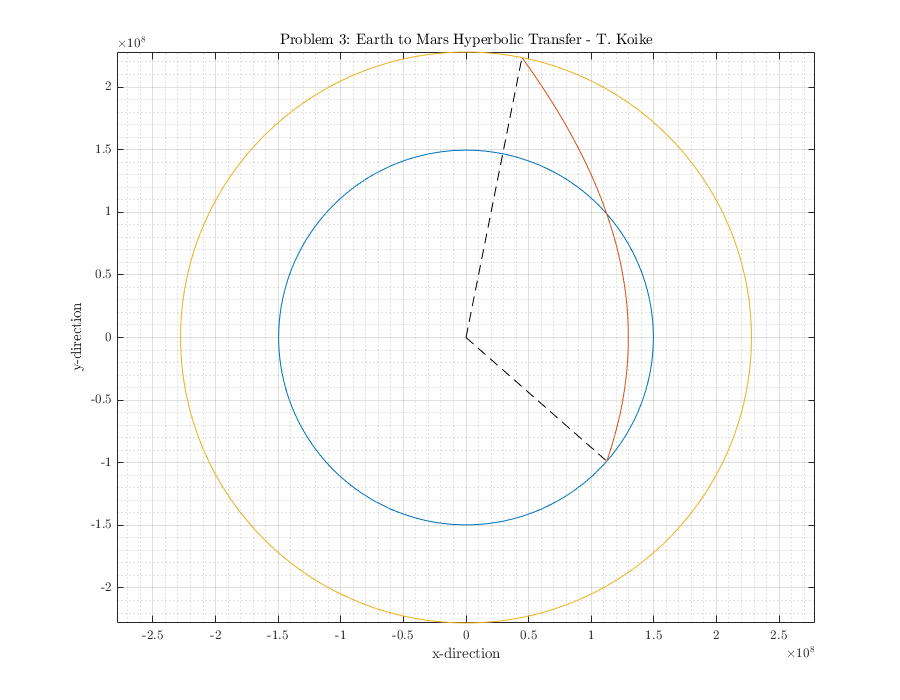

R_x = p ./ (1 + e * cosd(angles));
X_x = R_x .* cosd(angles); Y_x = R_x .* sind(angles);

% Mars Orbit
angles = 0:360;
X_mars = mars.smao * cosd(angles); Y_mars = mars.smao * sind(angles);

fig = figure("Renderer","painters","Position",[10 10 900 700]);
plot(X_earth, Y_earth)
hold on; grid on; grid minor; box on; axis equal;
plot(X_x, Y_x)
plot(X_mars, Y_mars)
plot([0, X_x(1)], [0, Y_x(1)], '--k')
plot([0, X_x(end)], [0, Y_x(end)], '--k')
hold off
title('Problem 3: Earth to Mars Hyperbolic Transfer - T. Koike')
xlabel('x-direction')
ylabel('y-direction')
saveas(fig, fullfile(fdir, 'p3_transfer.png'));

% (e)
v_inf_earth = Dv_dep;
h = 1000;
En_fb = v_inf_earth^2 / 2

En_fb = 198.1657

a_fb = -mu_earth / 2 / En_fb

a_fb = -1.0057e+03

e_fb = 1 - (earth.mer + h) / a_fb

e_fb = 8.3361

delta = 2 * asind(1 / e_fb)

delta = 13.7795

v_fb1 = vis_viva(earth.mer + h, a_fb, mu_earth)

v_fb1 = 22.4584

% (f)
v_inf_mars = Dv_arr;
h = 500;
En_fb = v_inf_mars^2 / 2

En_fb = 308.8075

a_fb = -mu_mars / 2 / En_fb

a_fb = -69.3447

e_fb = 1 - (mars.mer + h) / a_fb

e_fb = 57.1975

delta = 2 * asind(1 / e_fb)

delta = 2.0035

v_fb2 = vis_viva(mars.mer + h, a_fb, mu_mars)

v_fb2 = 25.2902